Consider the ODEs $u'=u$ and $u'=-u$. In each case we compute $\partial f/\partial u = \pm 1$, so the condition number bound is $e^{(b-a)}$ in both problems. However, they behave quite differently. In the case of exponential growth, $u'=u$, the bound is the actual condition number.

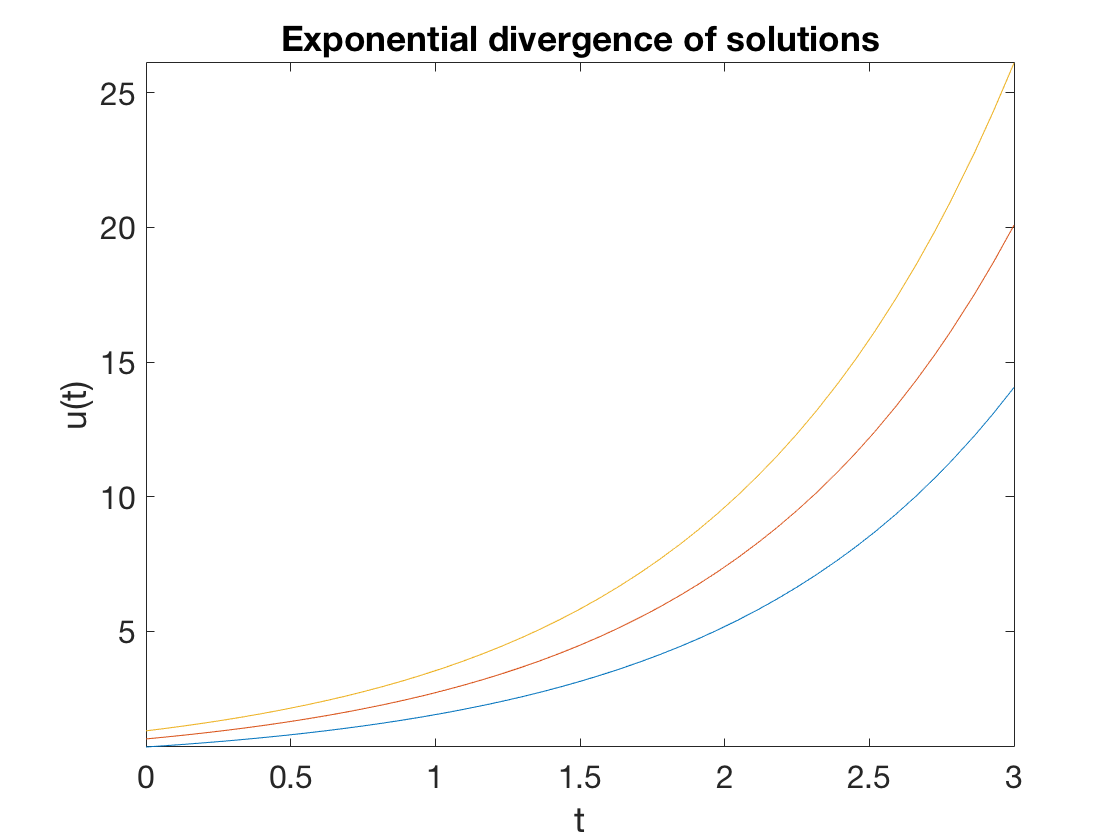

for u0 = [0.7 1 1.3]
    fplot(@(t) exp(t)*u0,[0 3]), hold on
end
xlabel('t'), ylabel('u(t)')   % ignore this line
title('Exponential divergence of solutions')   % ignore this line

But with $u'=-u$, solutions actually get closer together with time.

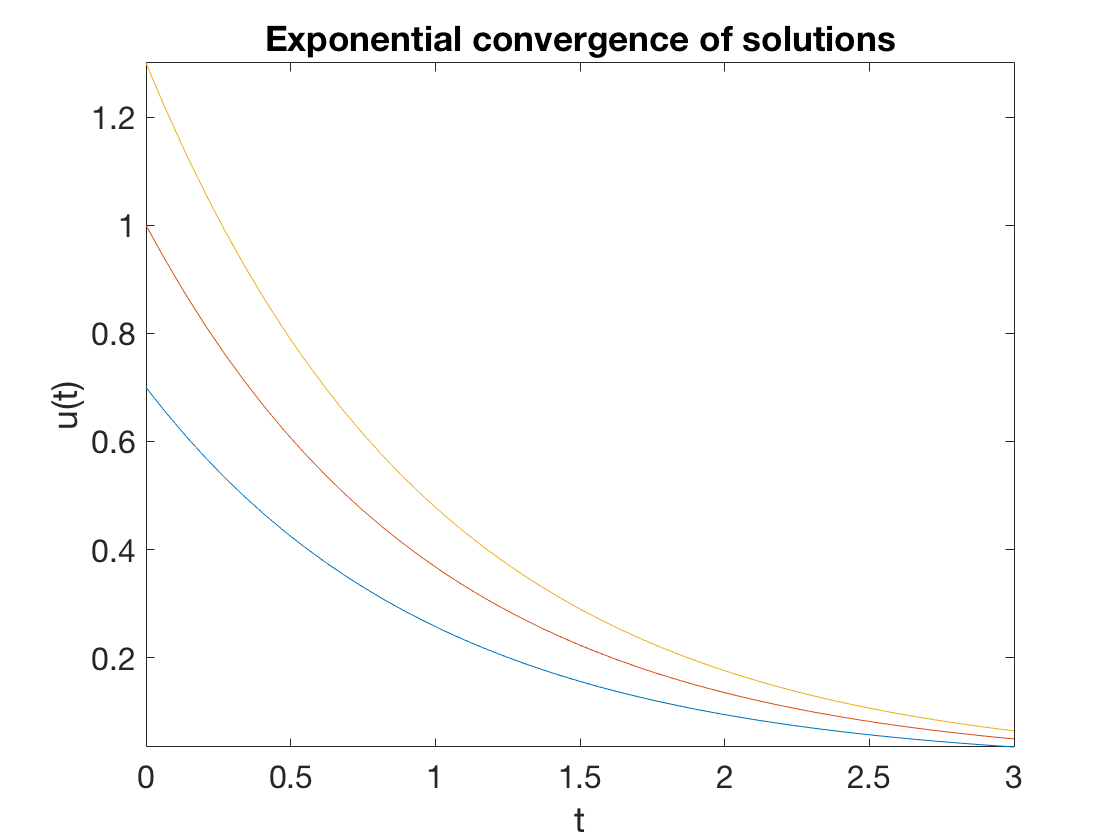

clf
for u0 = [0.7 1 1.3]
    fplot(@(t) exp(-t)*u0,[0 3]), hold on
end
xlabel('t'), ylabel('u(t)')   % ignore this line
title('Exponential convergence of solutions')   % ignore this line

In this case the actual condition number is one, due to the difference of solutions at the initial time. 